# Análise de Nyquist e do princípio do argumento de Cauchy

## Boas práticas

clear all;
close all;
clc;

## Referência

[https://www.mathworks.com/matlabcentral/answers/479681-how-to-plot-circle-with-direction](https://www.mathworks.com/matlabcentral/answers/479681-how-to-plot-circle-with-direction)

## Função para análise


$$F(s) = \frac{s+1}{s+2}$$



F = tf([1 1],[1 2])

F =
 
  s + 1
  -----
  s + 2
 
Continuous-time transfer function.



Curva $\gamma_1$ envolve o zero e não o polo:

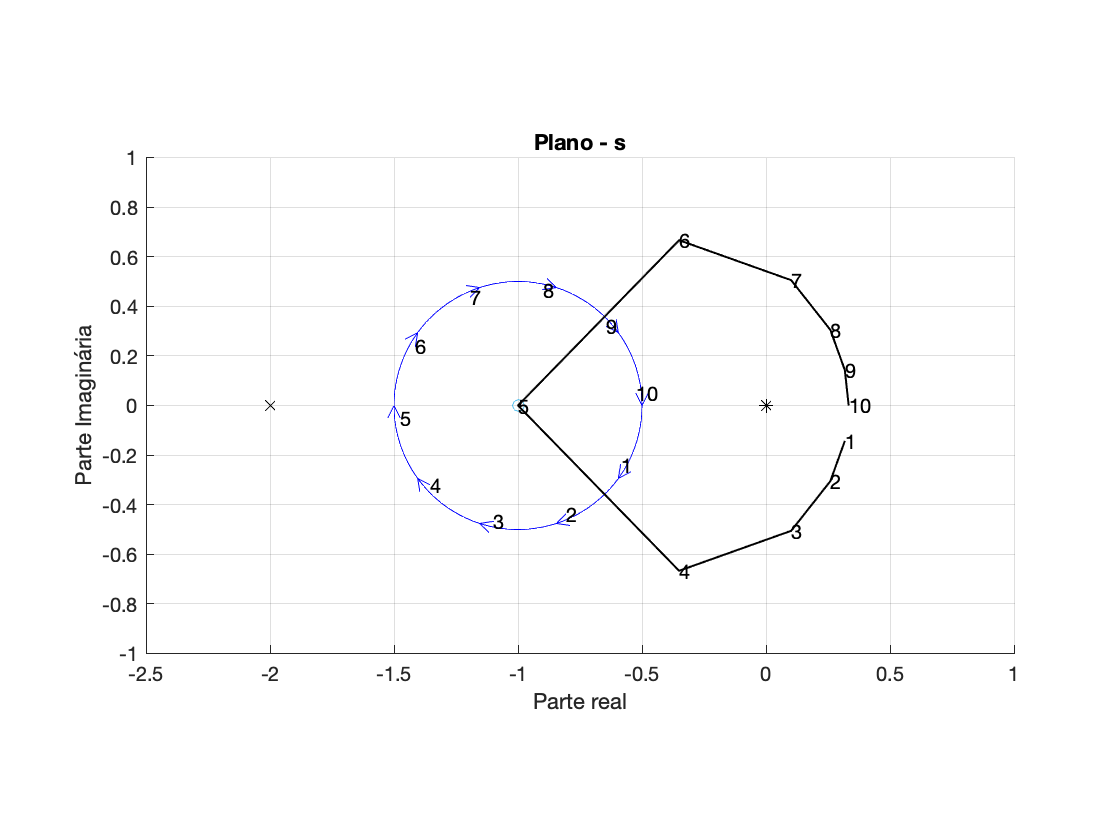

% Criando a função da curva gamma

figure(1)

r = 0.5;
cx = -1;
cy = 0;
cfun = @(tt) [cx+r*cos(tt); cy+r*sin(tt)];
xy = cfun(linspace(0,2*pi,361));
close all
hold on
plot(xy(1,:),xy(2,:),'b');

% Colocando sentido no circulo

m = 10; % number of arrows
h = 0.1*r; % height
w = 0.1*r; % width
dir = -1; % 1 anticlock, -1 clock
a = [-w/2 0 w/2;
      -dir*h  0 -dir*h];
for k=1:m
    tt = dir*2*pi*k/m;
    R = [cos(tt) -sin(tt);
         sin(tt)  cos(tt)];
    xy = cfun(tt)+  R*a;
    plot(xy(1,:),xy(2,:),'b');
    text(xy(1,1),xy(2,1),num2str(k))
    
    xy = cfun(tt);
    Fxy(k) = evalfr(F,xy(1)+j*xy(2));
    
end
axis equal
title('Plano - s');
xlabel('Parte real');
ylabel('Parte Imaginária');
plot(-2,0,'Kx',-1,0,'o',0,0,'k*');
axis([-2.5 1 -1 1]);
grid;
for k=1:m
    text(real(Fxy(k)),imag(Fxy(k)),num2str(k));    
end
    plot(real(Fxy),imag(Fxy),'k-','LineWidth' ,1)
    
xlim([-2.50 1.00])
ylim([-1.00 1.00])

Curva $\gamma_2$  envolve o zero e  o polo:

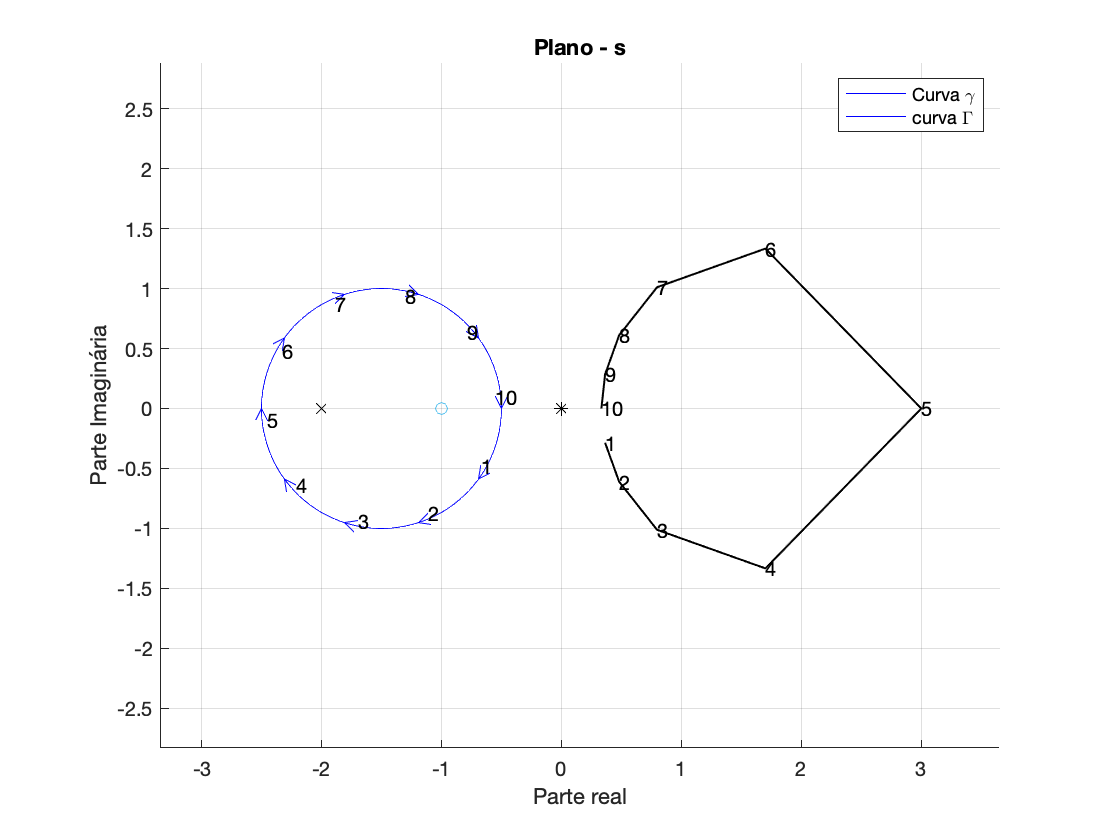

% Criando a função da curva gamma

figure(2)

r = 1;
cx = -1.5;
cy = 0;
cfun = @(tt) [cx+r*cos(tt); cy+r*sin(tt)];
xy = cfun(linspace(0,2*pi,361));
close all
hold on
plot(xy(1,:),xy(2,:),'b');

% Colocando sentido no circulo

m = 10; % number of arrows
h = 0.1*r; % height
w = 0.1*r; % width
dir = -1; % 1 anticlock, -1 clock
a = [-w/2 0 w/2;
      -dir*h  0 -dir*h];
for k=1:m
    tt = dir*2*pi*k/m;
    R = [cos(tt) -sin(tt);
         sin(tt)  cos(tt)];
    xy = cfun(tt)+  R*a;
    plot(xy(1,:),xy(2,:),'b');
    text(xy(1,1),xy(2,1),num2str(k))
    
    xy = cfun(tt);
    Fxy(k) = evalfr(F,xy(1)+j*xy(2));
    
end
axis equal
title('Plano - s');
xlabel('Parte real');
ylabel('Parte Imaginária');
plot(-2,0,'Kx',-1,0,'o',0,0,'k*');
axis([-2.5 1 -1 1]);
grid;
for k=1:m
    text(real(Fxy(k)),imag(Fxy(k)),num2str(k));    
end
    plot(real(Fxy),imag(Fxy),'k-','LineWidth' ,1)
    legend('Curva \gamma', 'curva \Gamma')
    
xlim([-3.34 3.65])
ylim([-2.83 2.88])

Curva $\gamma_3$ envolve o polo e não o zero:

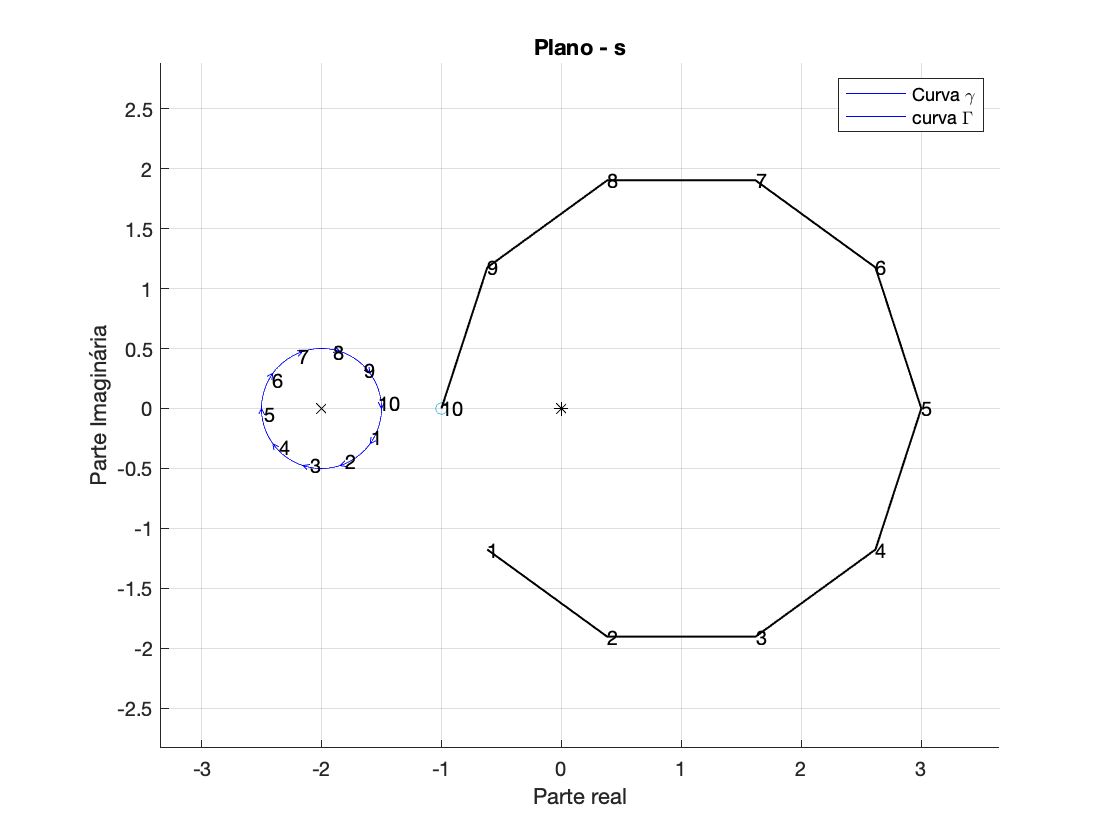

% Criando a função da curva gamma

figure(2)

r = 0.5;
cx = -2;
cy = 0;
cfun = @(tt) [cx+r*cos(tt); cy+r*sin(tt)];
xy = cfun(linspace(0,2*pi,361));
close all
hold on
plot(xy(1,:),xy(2,:),'b');

% Colocando sentido no circulo

m = 10; % number of arrows
h = 0.1*r; % height
w = 0.1*r; % width
dir = -1; % 1 anticlock, -1 clock
a = [-w/2 0 w/2;
      -dir*h  0 -dir*h];
for k=1:m
    tt = dir*2*pi*k/m;
    R = [cos(tt) -sin(tt);
         sin(tt)  cos(tt)];
    xy = cfun(tt)+  R*a;
    plot(xy(1,:),xy(2,:),'b');
    text(xy(1,1),xy(2,1),num2str(k))
    
    xy = cfun(tt);
    Fxy(k) = evalfr(F,xy(1)+j*xy(2));
    
end
axis equal
title('Plano - s');
xlabel('Parte real');
ylabel('Parte Imaginária');
plot(-2,0,'Kx',-1,0,'o',0,0,'k*');
axis([-2.5 1 -1 1]);
grid;
for k=1:m
    text(real(Fxy(k)),imag(Fxy(k)),num2str(k));    
end
    plot(real(Fxy),imag(Fxy),'k-','LineWidth' ,1)
    legend('Curva \gamma', 'curva \Gamma')
    
xlim([-3.34 3.65])
ylim([-2.83 2.88])